# Hybrid test: V8 dynamics and Pure Pursuit tracking

Integrates V8 plant equations and practice 4 controllers without modifying them. A new cone circuit combines straights, inside corners and outside corners. The historical description lists 6 and 14 m/s references; the executable configuration determines current cases. Results distinguish lap completion from lane exit. Original sources: CuatroruedasV8_bloqueo_ruedas.mlx and P4_seguimiento_trayectoria_ALUMNO.mlx.

% Source: CuatroruedasV8_bloqueo_ruedas.mlx | SHA256: 5502b64c9336f6cbfcc394f0d39e986e2266b3d37636013bea30260a9f8ffa1c
% Source: P4_seguimiento_trayectoria_ALUMNO.mlx | SHA256: 58965f692cf38b8a1928c7ddcf16276dcb8aee7fd3a043acc123b057dd832679
%% V8 dynamics and Pure Pursuit from practice 4
% Standalone file. V8 physical functions and P4 controllers
% are included without changing their equations. It neither reads nor writes
% the originals and does not need external Ensayos helpers.
% Track geometry, the test integrator and plots are new.
% Does not include ESC, ABS, TCS or corner-speed planning.

%% Original V8 parameters
p = struct(); 

p.m    = 230;      % mass [kg]
p.g    = 9.81;     % gravity [m/s^2]
p.rho  = 1.225;    % air density [kg/m^3]
p.Cd   = 1.0;      % aerodynamic coefficient
p.Af   = 1.1;      % frontal area [m^2]
p.fr  = 0.022;    % rolling-resistance coefficient
p.Fx_drive_max = 2500;   % maximum driving force [N]
p.Fx_brake_max = 5000;   % maximum braking force [N]
p.theta = 0;      % road inclination [rad]

% Define the parameters needed to describe the vehicle's
% lateral dynamics here.
p.ld = 0.765; % [m] CG to front axle, longitudinal distance
p.lt = 0.765; % [m] CG to rear axle, longitudinal distance
p.lyd = 0.600; % [m] CG to front wheels, lateral distance
p.lyt = 0.600; % [m] CG to rear wheels, lateral distance
p.hcg = 0.230; % [m] centre-of-gravity height
% Wheel coordinates relative to the CG
% Order: DI, DD, TI, TD
p.xw = [p.ld,p.ld,-p.lt,-p.lt];
p.L = p.ld+p.lt; 
p.yw = [p.lyd, -p.lyd, p.lyt, -p.lyt];
p.td = p.lyd + p.lyt;
p.tt = p.td; 
p.Iz = 130; % [kg m^2] yaw inertia
p.Cad = 35000; % [N/rad] front cornering stiffness
p.Cat = 50000; % [N/rad] rear cornering stiffness --> understeering vehicle
p.Caw = [p.Cad/2, p.Cad/2, p.Cat/2, p.Cat/2];
p.nCa = 0.8; 
p.mu_t = 1.5; % rear tyre friction
p.mu_d = 0.95*p.mu_t; % front tyre friction
p.muw = [p.mu_d, p.mu_d, p.mu_t, p.mu_t];
% Lateral adhesion loss under excess traction demand
p.Kslip = 3; % Rear-wheel lateral-loss intensity
% Time dynamics of lateral loss and recovery
p.tau_slip_loss = 0.03; % loss time constant [s]
p.tau_slip_rec  = 0.50; % recovery time constant [s]
% Adhesion loss under excess braking demand.
% Initial test values, awaiting calibration.
% Two braking modes: normal and approximate lock.
% Illustrative parameters awaiting experimental calibration.
p.brake_slide_ratio = 0.68; % mu_min / mu_base (high-speed limit)
p.v_brake_slide = 15;      % Speed scale [m/s]
p.brake_lock_on = 1.02;    % Entry: demand / nominal capacity
p.brake_lock_off = 0.90;   % Hysteretic exit
p.tau_brake_loss = 0.03;   % Transition to lock-mode target [s]
p.tau_brake_rec = 0.10;    % Recovery under partial brake relief [s]
p.tau_brake_release = 0.01;% Rapid full-release recovery: 95% in 30 ms

% Force allocation
p.Fzd0 = p.m*p.g*p.lt/p.L; % [N] initial front-axle vertical load
p.Fzt0 = p.m*p.g*p.ld/p.L; % [N] initial rear-axle vertical load
p.Fzw0 = [p.Fzd0/2, p.Fzd0/2, p.Fzt0/2, p.Fzt0/2]; % [N] initial vertical load per wheel
p.drive_w = [0, 0, 0.5, 0.5]; % Driving-force allocation during acceleration
p.brake_w = [0.3, 0.3, 0.2, 0.2]; % Longitudinal-force allocation during braking
p.kRoll = 0.5; % front share of roll moment (replace with a suspension model later)



%% P4 controllers and test configuration
p.Kp_v=800; p.Ki_v=200;
p.Ld0=2.0; p.kLd=0.3; p.delta_max=0.5;
p.dt=0.002;
ensayo.ancho=3.0;             % distance between track boundaries [m]
ensayo.pasoTrayectoria=0.25;  % maximum geometric spacing [m]
ensayo.pasoConos=3.0;         % approximate cone spacing [m]
ensayo.velocidades=[6 10];    % moderate and demanding [m/s]
ensayo.errorAbandono=10;      % stop if tracking leaves the reference widely [m]

%% Circuit with straights, outside and inside corners
pista=generarCircuitoHibrido(ensayo);
centro=pista.centro; cono_izq=pista.conoIzq; cono_der=pista.conoDer;
fprintf('\nCircuit: %.2f m; width %.1f m; %d straights and %d corners.\n', pista.longitud,ensayo.ancho,height(pista.curvas),height(pista.curvas));


Circuito: 272.24 m; ancho 3.0 m; 8 rectas y 8 curvas.


disp(pista.curvas);

    Curva    Radio_m      Sentido         Tipo       CentroX_m    CentroY_m
    _____    _______    ___________    __________    _________    _________

      1        10       "izquierda"    "exterior"       10           10    
      2        14       "izquierda"    "exterior"       56           14    
      3        10       "izquierda"    "exterior"       60           40    
      4         6       "izquierda"    "exterior"       51           44    
      5         6       "derecha"      "interior"       39           34    
      6         7       "derecha"      "interior"       32           35    
      7         9       "izquierda"    "exterior"       16           51    
      8        12       "izquierda"    "exterior"       12           48    




%% Independent runs at two speed levels
resultados=cell(numel(ensayo.velocidades),1);
for caso=1:numel(ensayo.velocidades)
    pCaso=p; pCaso.v_set=ensayo.velocidades(caso);
    resultados{caso}=simularHibrido(pCaso,pista,ensayo);
end

Caso 6.0 m/s: vuelta completada, t=44.16 s, max |e|=1.016 m.
Caso 10.0 m/s: vuelta completada, t=26.33 s, max |e|=1.123 m.


histNominal=resultados{1};
histExigente=resultados{2};

%% Summary and plots
resumen=resumirHibrido(resultados,ensayo);
disp(resumen);

    Vref_ms    VueltaCompleta    TiempoSimulado_s    ErrorMedio_m    ErrorRMS_m    ErrorMax_m    TiempoFueraCarril_pct    Saturacion_pct    Bloqueo_pct
    _______    ______________    ________________    ____________    __________    __________    _____________________    ______________    ___________

       6           true               44.164           0.28941        0.40829        1.0158                0                  1.6846             0     
      10           true               26.334           0.37638        0.52114        1.1233                0                  12.227             0     



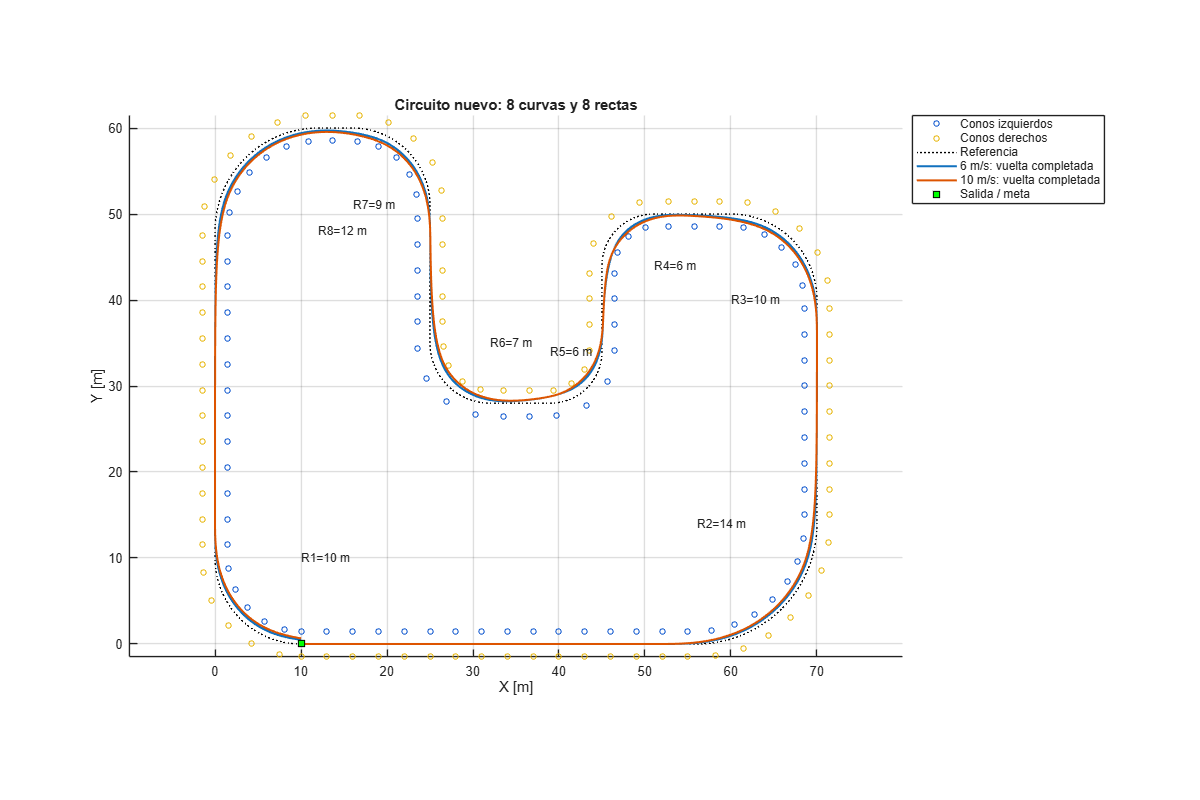

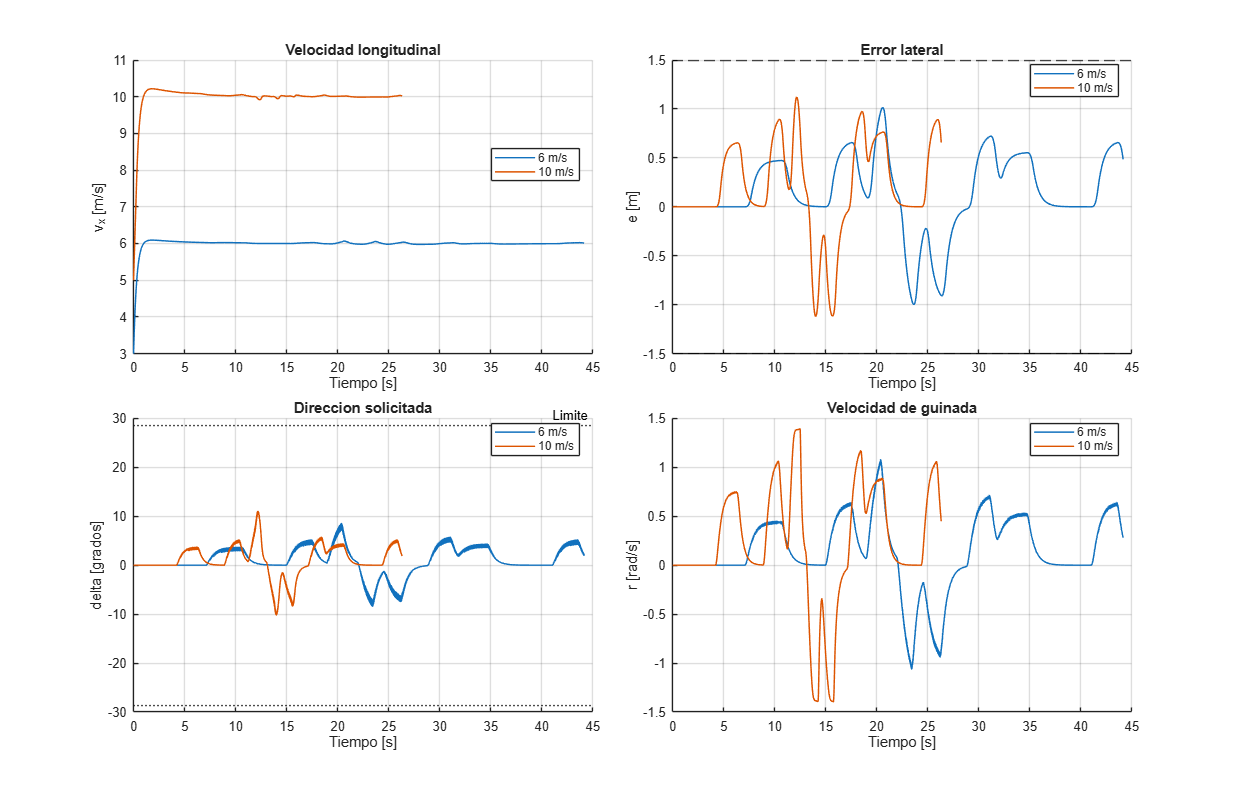

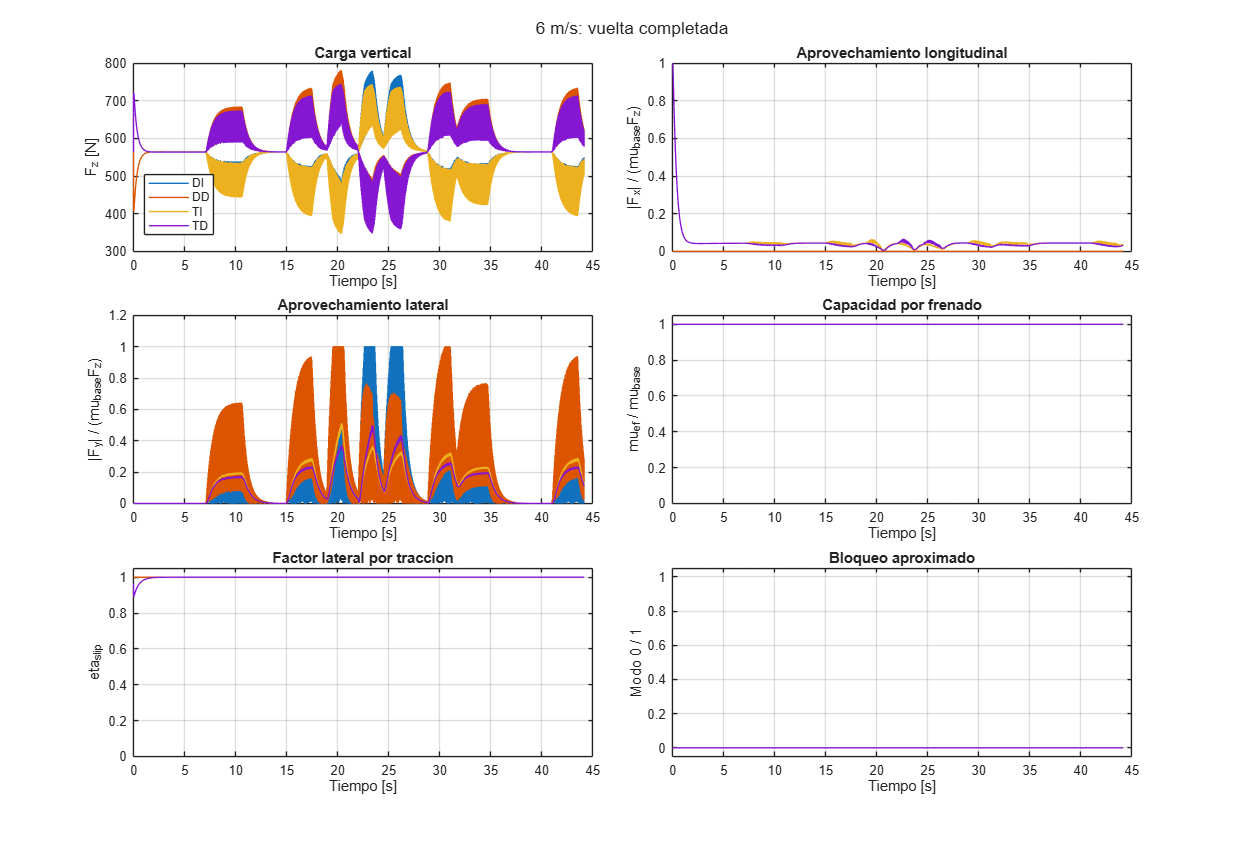

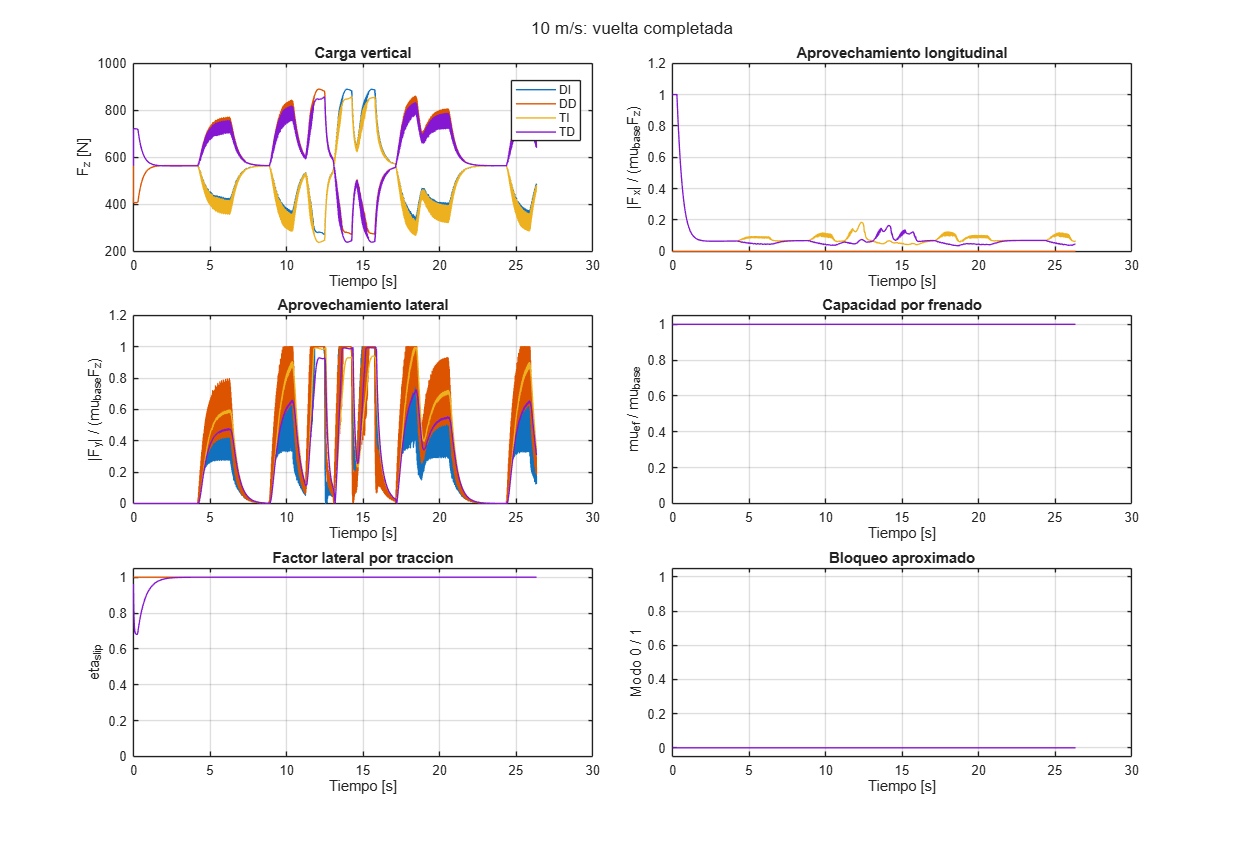

mostrarHibrido(resultados,pista,ensayo,p);

fprintf(['\nInterpretation: completing a lap does not guarantee staying on track.\n' ...
    'The track-boundary criterion uses the CG, not the body envelope.\n' ...
    'Lock curves represent the V8 phenomenological approximation.\n']);


Interpretacion: completar la vuelta no garantiza permanecer en el carril.
El criterio de carril corresponde al centro de gravedad, sin envolvente de carroceria.
Las curvas de bloqueo representan la aproximacion fenomenologica de V8.



%% Physical functions and controllers copied from the originals
function [z_next, tele] = pasoDinamico(z, u, p, dt)
    % Complete state (20x1), wheel order DI, DD, TI, TD:
    % 1:6   X, Y, psi, vx, vy, r (motion)
    % 7:8   previous ax, ay (quasi-static transfer)
    % 9:12  eta_slip (lateral adhesion memory)
    % 13:16 eta_brake (braking-capacity memory)
    % 17:20 bloqueo_w (discrete mode, 0 or 1)
    if ~isvector(z) || numel(z) ~= 20
        error('pasoDinamico:EstadoInvalido', 'The dynamic state requires 20 components; initialize its memory.');
    end
    z = z(:);
    ax_prev = z(7);
    ay_prev = z(8);
    eta_prev = z(9:12).';
    eta_brake_prev = z(13:16).';
    bloqueo_prev = logical(z(17:20).');
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    vy = z(5);
    r = z(6);
    L = p.ld + p.lt;
    xw = p.xw;
    yw = p.yw;


    % vx_c = max(vx, 1.0); % corrected speed to avoid division by zero,
    % disabled now that the model uses atan2

    
    %% 1. Individual wheel kinematics

    delta_w = [delta, delta, 0, 0];

    % Wheel-centre velocities in chassis coordinates
    vxw = vx - r .* p.yw;
    vyw = vy + r .* p.xw;

    % Velocities projected into individual wheel coordinates
    vxw_local =  vxw .* cos(delta_w) + vyw .* sin(delta_w);
    vyw_local = -vxw .* sin(delta_w) + vyw .* cos(delta_w);

    % Individual slip angles
    alpha_w = delta_w-atan2(vyw_local, vxw_local);

    %% Define adhesion limits
    % Longitudinal transfer between axles
    dFzx = p.m*ax_prev*p.hcg/p.L;

    % Lateral transfer within each axle
    dFzyd = p.kRoll*p.m*ay_prev*p.hcg/p.td;
    dFzyt = (1-p.kRoll)*p.m*ay_prev*p.hcg/p.tt;

    % Order: DI, DD, TI, TD
    Fzw = p.Fzw0 + [-dFzx/2, -dFzx/2, dFzx/2, dFzx/2] + [-dFzyd, dFzyd, -dFzyt,dFzyt];
    % Longitudinal grip
    % Lateral forces per wheel
    Caw = p.Caw .* (Fzw ./ p.Fzw0).^p.nCa;
    Fyw = Caw .* alpha_w;

    % Longitudinal driving-force allocation per wheel
    if Fx >= 0
        Fxw_sol = Fx .* p.drive_w;
    else
        Fxw_sol = Fx .* p.brake_w;
    end

    %% Normal braking and approximate locking with memory
    Fmax_peak_w = p.muw .* Fzw;
    demanda_freno_w = max(0,-Fxw_sol);
    ratio_freno_w = demanda_freno_w ./ max(Fmax_peak_w,eps);
    s_brake_w = max(0,ratio_freno_w-1);

    % Hysteresis relative to the NOMINAL limit, not the reduced limit.
    bloqueo_w = logical(bloqueo_prev);
    bloqueo_w(ratio_freno_w > p.brake_lock_on) = true;
    bloqueo_w(ratio_freno_w < p.brake_lock_off) = false;
    freno_suelto_w = (demanda_freno_w == 0);
    bloqueo_w(freno_suelto_w) = false;

    % Assumed locked wheel: sliding speed equals local forward speed.
    % Capacity approaches mu_base at low v and mu_min at high v.
    eta_bloq_vel = p.brake_slide_ratio + (1-p.brake_slide_ratio).*exp(-abs(vxw_local)/p.v_brake_slide);
    eta_brake_obj = ones(1,4);
    eta_brake_obj(bloqueo_w) = eta_bloq_vel(bloqueo_w);

    eta_brake = eta_brake_prev;
    for i = 1:4
        if freno_suelto_w(i)
            tau = p.tau_brake_release;
        elseif bloqueo_w(i)
            tau = p.tau_brake_loss;
        else
            tau = p.tau_brake_rec;
        end
        factor = 1-exp(-dt/tau);
        eta_brake(i) = eta_brake_prev(i) + factor*(eta_brake_obj(i)-eta_brake_prev(i));
    end
    eta_brake = max(p.brake_slide_ratio,min(1,eta_brake));

%% Friction circle with effective capacity

% The loss modifies the combined Fx/Fy limit only once.
Fmax_w = eta_brake .* Fmax_peak_w;

% Extension of the existing lock mode (simplified model):
% unit longitudinal factor: preserves the calculated mu_eff*Fz limit.
% zero lateral factor: removes Fy demand BEFORE circle saturation.
factor_x_bloqueo = ones(1,4);
factor_y_bloqueo = double(~bloqueo_w);
Fyw = factor_y_bloqueo .* Fyw;

Fres_w = hypot(Fxw_sol,Fyw);
lambda_w = min(ones(1,4), ...
    Fmax_w ./ max(Fres_w,eps));

Fxw = lambda_w .* Fxw_sol;
Fyw = lambda_w .* Fyw;

    
    %% Progressive lateral adhesion loss and recovery

    % Excess longitudinal demand relative to adhesion
    s_w = max(0, abs(Fxw_sol) ./ max(Fmax_w,eps) - 1);

    % Target lateral-capacity factor
    eta_obj = ones(1,4);

    % Additional loss is only triggered during driving
    if Fx > 0
        eta_obj(3:4) = 1 ./ (1 + p.Kslip .* s_w(3:4));
    end

    % Adhesion state inherited from the previous step
    eta_slip = eta_prev;

    % Rear-wheel time update
    for i = 3:4

        % Rapid loss or slow recovery
        if eta_obj(i) < eta_prev(i)
            tau = p.tau_slip_loss;
        else
            tau = p.tau_slip_rec;
        end

        % Stable exponential integration
        factor = 1 - exp(-dt/tau);

        eta_slip(i) = eta_prev(i) + factor * (eta_obj(i) - eta_prev(i));

    end

    % Bound the factor to its physically defined interval
    eta_slip = max(0,min(1,eta_slip));

    % Rear lateral-force reduction
    Fyw(3:4) = eta_slip(3:4) .* Fyw(3:4);

    % In lock mode, braking acts exclusively along CHASSIS X.
    % Removing only local Fy would still allow steering through Fx*sin(delta).
    % Outside lock mode, retain the original transformation.
    % This is a simplified restriction, not isotropic locked-wheel friction.
    delta_fuerza_w = delta_w;
    delta_fuerza_w(bloqueo_w) = 0;
    Fxw_chasis = Fxw .* cos(delta_fuerza_w) - Fyw .* sin(delta_fuerza_w);
    Fyw_chasis = Fxw .* sin(delta_fuerza_w) + Fyw .* cos(delta_fuerza_w);

    % Resultant forces and moment
    SumFx = sum(Fxw_chasis); % Total longitudinal force
    SumFy = sum(Fyw_chasis); % Total lateral force
    SumMz = sum(p.xw .* Fyw_chasis - p.yw .* Fxw_chasis); % Yaw moment about the CG

    % Telemetry: current-step data without changing forces or dynamics
    tele.alpha_w = alpha_w;
    tele.Fxw = Fxw;
    tele.Fyw = Fyw;
    tele.Fzw = Fzw;
    tele.Caw = Caw;
    tele.Mzw = p.xw .* Fyw_chasis - p.yw .* Fxw_chasis;
    tele.Mz_long = sum(p.xw .* (Fxw .* sin(delta_fuerza_w)) - p.yw .* (Fxw .* cos(delta_fuerza_w)));
    tele.Mz_lat = SumMz - tele.Mz_long;
    tele.lambda_w = lambda_w;
    tele.Fmax_w = Fmax_w;
    tele.s_w = s_w;
    tele.eta_slip = eta_slip;
    tele.eta_obj = eta_obj;
    tele.Fmax_peak_w = Fmax_peak_w;
    tele.s_brake_w = s_brake_w;
    tele.eta_brake = eta_brake;
    tele.eta_brake_obj = eta_brake_obj;
    tele.bloqueo_w = bloqueo_w;
    tele.mu_eff_w = p.muw .* eta_brake;
    tele.factor_x_bloqueo = factor_x_bloqueo;
    tele.factor_y_bloqueo = factor_y_bloqueo;
    tele.delta_fuerza_w = delta_fuerza_w;
    tele.Fxw_chasis = Fxw_chasis;
    tele.Fyw_chasis = Fyw_chasis;

    % Longitudinal dynamics (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    
    % equations of motion
    ax_fis = (SumFx - Ra - sign(vx)*Rr - Rg)/p.m;
    ay_fis = SumFy/p.m;
    ax  = ax_fis + vy*r; % retain centripetal coupling
    ay = ay_fis - vx*r; 
    dr = SumMz/p.Iz;   
    tele.ax = ax_fis;
    tele.ay = ay_fis;

    vx_next = max(vx + ax*dt,0);
    vy_next = vy + ay*dt; 
    r_next = r + dr*dt;
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next; ...
        ax_fis; ay_fis; eta_slip(:); eta_brake(:); double(bloqueo_w(:))]; 
end

function z = inicializarEstadoDinamico(z)
    % Preserve memory when a complete state is supplied.
    z = z(:);
    if numel(z) == 6
        z = [z; zeros(2,1); ones(4,1); ones(4,1); zeros(4,1)];
    elseif numel(z) ~= 20
        error('Dynamic state: 6 or 20 components are required.');
    end
end

function [Fx, e_int] = controlVelocidadSimple(v_ref, vx, e_int, dt, p)
    e = v_ref - vx;  e_int = e_int + e*dt;
    Fx = p.Kp_v*e + p.Ki_v*e_int;
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max);
end

function [delta, mem] = controlLateral(est, path, p, mem)
    x = est.X; y = est.Y; psi = est.psi; vx = est.vx;
    L = p.ld + p.lt;
    Ld = p.Ld0 + p.kLd*max(vx, 0);

    % Extract the target point where the lookahead distance intersects
    % the reference path.
    [tx, ty, mem.idx] = buscarPuntoAdelante(path, x, y, Ld, mem.idx);

    % calculate geometry

    alpha = atan2(ty-y,tx-x) -psi;
    alpha = atan2(sin(alpha), cos(alpha)); % normalize steering to [-pi,pi]
    delta = atan2(2*L*sin(alpha),Ld);

    delta = max(min(delta, p.delta_max), -p.delta_max);
end

function [tx, ty, idx] = buscarPuntoAdelante(path, x, y, Ld, idx)
% Return the target point and updated index.
    N = size(path,1);
    
    d2 = (path(:,1)-x).^2 + (path(:,2)-y).^2; % after deviation, re-anchor the index to the nearest point
    [~, icerca] = min(d2);
    idx = icerca;

    for step = 0:N % advance along the path until reaching Ld
        j = mod(idx-1+step,N) +1;
        if hypot(path(j,1)-x, path(j,2)-y) >= Ld
            tx = path(j,1);  ty = path(j,2);  idx = j;  return;
        end
    end
    j = mod(idx-1+round(N/10), N) + 1; % if no point is far enough, use the furthest available point ahead
    tx = path(j,1);  ty = path(j,2);  idx = j;
end

function e_ct = errorLateral(x, y, path) % positive e means left of the reference path
    d2 = (path(:,1)-x).^2 + (path(:,2)-y).^2;
    [~,i] = min(d2);  j = mod(i, size(path,1)) + 1;
    tang = atan2(path(j,2)-path(i,2), path(j,1)-path(i,1));
    dx = x-path(i,1); dy = y-path(i,2);
    e_ct = -sin(tang)*dx + cos(tang)*dy;
end

%% New geometry: rounded polygon with an inward section
function pista=generarCircuitoHibrido(cfg)
vertices=[0 0;70 0;70 50;45 50;45 28;25 28;25 60;0 60];
radios=[10 14 10 6 6 7 9 12]';
n=size(vertices,1); entrada=zeros(n,2); salida=entrada; centros=entrada;
angulos=zeros(n,1); giros=zeros(n,1);
for i=1:n
    ant=mod(i-2,n)+1; sig=mod(i,n)+1;
    a=vertices(i,:)-vertices(ant,:); a=a/norm(a);
    b=vertices(sig,:)-vertices(i,:); b=b/norm(b);
    giros(i)=atan2(a(1)*b(2)-a(2)*b(1),dot(a,b));
    d=radios(i)*tan(abs(giros(i))/2);
    entrada(i,:)=vertices(i,:)-d*a; salida(i,:)=vertices(i,:)+d*b;
    centros(i,:)=entrada(i,:)+sign(giros(i))*radios(i)*[-a(2) a(1)];
    angulos(i)=atan2(entrada(i,2)-centros(i,2),entrada(i,1)-centros(i,1));
end
xy=salida(1,:); tangente=[1 0]; curvatura=0;
for iter=1:n
    i=mod(iter,n)+1; ant=mod(i-2,n)+1;
    desde=salida(ant,:); hasta=entrada(i,:);
    tramo=hasta-desde; longitud=norm(tramo); direccion=tramo/longitud;
    assert(dot(tramo,vertices(i,:)-vertices(ant,:))>0,'Corner radii encroach on a straight segment.');
    np=max(1,ceil(longitud/cfg.pasoTrayectoria));
    q=(1:np)'/np;
    xy=[xy;desde+q.*tramo]; %#ok<AGROW>
    tangente=[tangente;repmat(direccion,np,1)]; %#ok<AGROW>
    curvatura=[curvatura;zeros(np,1)]; %#ok<AGROW>
    np=max(2,ceil(abs(giros(i))*radios(i)/cfg.pasoTrayectoria));
    theta=angulos(i)+giros(i)*(1:np)'/np;
    xy=[xy;centros(i,:)+radios(i)*[cos(theta) sin(theta)]]; %#ok<AGROW>
    tangente=[tangente;sign(giros(i))*[-sin(theta) cos(theta)]]; %#ok<AGROW>
    curvatura=[curvatura;repmat(sign(giros(i))/radios(i),np,1)]; %#ok<AGROW>
end
assert(norm(xy(end,:)-xy(1,:))<1e-9,'The circuit does not close.');
xy(end,:)=[]; tangente(end,:)=[]; curvatura(end)=[];
normal=[-tangente(:,2) tangente(:,1)];
s=[0;cumsum(vecnorm(diff(xy),2,2))];
longitud=s(end)+norm(xy(end,:)-xy(1,:));
izq=xy+cfg.ancho/2*normal; der=xy-cfg.ancho/2*normal;
sConos=(0:cfg.pasoConos:longitud-1e-9)';
pista.centro=xy; pista.s=s; pista.longitud=longitud;
pista.tangente=tangente; pista.curvatura=curvatura;
pista.bordeIzq=izq; pista.bordeDer=der;
pista.conoIzq=interp1([s;longitud],[izq;izq(1,:)],sConos);
pista.conoDer=interp1([s;longitud],[der;der(1,:)],sConos);
pista.segmentoA=xy; pista.segmentoB=circshift(xy,-1,1);
pista.segmentoD=pista.segmentoB-pista.segmentoA;
pista.segmentoL=vecnorm(pista.segmentoD,2,2);
sentido=repmat("left",n,1); sentido(giros<0)="right";
tipo=repmat("outside",n,1); tipo(giros<0)="inside";
pista.curvas=table((1:n)',radios,sentido,tipo,centros(:,1),centros(:,2), ...
    'VariableNames',{'Curva','Radio_m','Sentido','Tipo','CentroX_m','CentroY_m'});
end

function h=simularHibrido(p,pista,cfg)
dt=p.dt; Tmax=max(60,2*pista.longitud/p.v_set); N=ceil(Tmax/dt);
psi0=atan2(pista.tangente(1,2),pista.tangente(1,1));
z=inicializarEstadoDinamico([pista.centro(1,:)';psi0;p.v_set*0.5;0;0]);
mem.idx=1; e_int=0; avance=0; sPrev=0; distancia=0;
h.t=zeros(N,1); h.z=zeros(N,20); h.delta=zeros(N,1); h.Fx_sol=zeros(N,1);
h.ect=zeros(N,1); h.ect_P4=zeros(N,1); h.s=zeros(N,1); h.distancia=zeros(N,1);
h.r_ref=zeros(N,1); h.ax=zeros(N,1); h.ay=zeros(N,1);
campos={'Fxw','Fyw','Fzw','Fmax_w','Fmax_peak_w','lambda_w','eta_brake','eta_slip','Caw','bloqueo_w'};
for j=1:numel(campos), h.(campos{j})=zeros(N,4); end
h.completa=false; h.motivo="time limit";
for k=1:N
    [ect,sActual,idx]=proyectarCircuito(z(1:2)',pista);
    ds=sActual-sPrev;
    if ds < -pista.longitud/2, ds=ds+pista.longitud; end
    if ds > pista.longitud/2, ds=ds-pista.longitud; end
    avance=avance+ds; sPrev=sActual;
    est.X=z(1); est.Y=z(2); est.psi=z(3); est.vx=z(4); est.vy=z(5); est.r=z(6);
    [delta,mem]=controlLateral(est,pista.centro,p,mem);
    [Fx,e_int]=controlVelocidadSimple(p.v_set,z(4),e_int,dt,p);
    [zNext,tele]=pasoDinamico(z,[Fx;delta],p,dt);
    if ~isreal(zNext) || any(~isfinite(zNext)) || ~isreal(tele.Fzw) || any(tele.Fzw<0)
        error('Invalid state or loads: case %.1f m/s, t=%.3f s.',p.v_set,(k-1)*dt);
    end
    h.t(k)=(k-1)*dt; h.z(k,:)=z'; h.delta(k)=delta; h.Fx_sol(k)=Fx;
    h.ect(k)=ect; h.ect_P4(k)=errorLateral(z(1),z(2),pista.centro);
    h.s(k)=avance; h.distancia(k)=distancia;
    h.r_ref(k)=z(4)*pista.curvatura(idx);
    h.ax(k)=tele.ax; h.ay(k)=tele.ay;
    for j=1:numel(campos), h.(campos{j})(k,:)=tele.(campos{j}); end
    if avance>=pista.longitud && distancia>0.9*pista.longitud
        h.completa=true; h.motivo="lap completed"; break
    end
    if abs(ect)>cfg.errorAbandono
        h.motivo="tracking error exceeded 10 m"; break
    end
    distancia=distancia+norm(zNext(1:2)-z(1:2)); z=zNext;
end
camposRecortar=[{'t','z','delta','Fx_sol','ect','ect_P4','s','distancia','r_ref','ax','ay'},campos];
for j=1:numel(camposRecortar), h.(camposRecortar{j})=h.(camposRecortar{j})(1:k,:); end
h.v_set=p.v_set;
h.aprov_long=abs(h.Fxw)./max(h.Fmax_peak_w,eps);
h.aprov_lat=abs(h.Fyw)./max(h.Fmax_peak_w,eps);
h.aprov_total=hypot(h.Fxw,h.Fyw)./max(h.Fmax_w,eps);
h.fueraCarril=abs(h.ect)>cfg.ancho/2;
fprintf('Case %.1f m/s: %s, t=%.2f s, max |e|=%.3f m.\n', ...
    p.v_set,h.motivo,h.t(end),max(abs(h.ect)));
end

function [ect,sActual,idx]=proyectarCircuito(pos,pista)
rel=pos-pista.segmentoA;
q=sum(rel.*pista.segmentoD,2)./pista.segmentoL.^2;
q=min(max(q,0),1);
pie=pista.segmentoA+q.*pista.segmentoD;
[~,idx]=min(sum((pos-pie).^2,2));
d=pos-pie(idx,:); tang=pista.segmentoD(idx,:)/pista.segmentoL(idx);
ect=-tang(2)*d(1)+tang(1)*d(2);
sActual=mod(pista.s(idx)+q(idx)*pista.segmentoL(idx),pista.longitud);
end

function tabla=resumirHibrido(resultados,cfg)
n=numel(resultados); velocidad=zeros(n,1); completa=false(n,1); tiempo=velocidad;
errorMedio=velocidad; errorRMS=velocidad; errorMax=velocidad;
fuera=velocidad; saturacion=velocidad; bloqueo=velocidad;
for i=1:n
    h=resultados{i}; velocidad(i)=h.v_set; completa(i)=h.completa; tiempo(i)=h.t(end);
    errorMedio(i)=mean(abs(h.ect)); errorRMS(i)=sqrt(mean(h.ect.^2));
    errorMax(i)=max(abs(h.ect)); fuera(i)=100*mean(abs(h.ect)>cfg.ancho/2);
    saturacion(i)=100*mean(any(h.lambda_w<1-1e-6,2));
    bloqueo(i)=100*mean(any(h.bloqueo_w~=0,2));
end
tabla=table(velocidad,completa,tiempo,errorMedio,errorRMS,errorMax,fuera,saturacion,bloqueo, ...
    'VariableNames',{'Vref_ms','VueltaCompleta','TiempoSimulado_s','ErrorMedio_m', ...
    'ErrorRMS_m','ErrorMax_m','TiempoFueraCarril_pct','Saturacion_pct','Bloqueo_pct'});
end

function mostrarHibrido(resultados,pista,cfg,p)
colores=lines(numel(resultados)); ruedas={'DI','DD','TI','TD'};
figure('Name','Hybrid - circuit and trajectories','Color','w','Position',[80 80 1200 800]);
hold on; axis equal; grid on;
plot(pista.conoIzq(:,1),pista.conoIzq(:,2),'o','Color',[0 .3 .8],'MarkerSize',4,'DisplayName','Left cones');
plot(pista.conoDer(:,1),pista.conoDer(:,2),'o','Color',[.9 .7 0],'MarkerSize',4,'DisplayName','Right cones');
plot([pista.centro(:,1);pista.centro(1,1)],[pista.centro(:,2);pista.centro(1,2)],'k:','DisplayName','Reference');
for i=1:numel(resultados)
    h=resultados{i}; plot(h.z(:,1),h.z(:,2),'Color',colores(i,:),'LineWidth',1.5, ...
        'DisplayName',sprintf('%.0f m/s: %s',h.v_set,h.motivo));
end
for i=1:height(pista.curvas)
    text(pista.curvas.CentroX_m(i),pista.curvas.CentroY_m(i), ...
        sprintf('R%d=%g m',i,pista.curvas.Radio_m(i)),'FontSize',9);
end
plot(pista.centro(1,1),pista.centro(1,2),'ks','MarkerFaceColor','g','DisplayName','Start / finish');
xlabel('X [m]'); ylabel('Y [m]'); title('New circuit: 8 corners and 8 straights');
legend('Location','bestoutside');

figure('Name','Hybrid - tracking and controls','Color','w','Position',[90 90 1250 800]);
tiledlayout(2,2,'TileSpacing','compact');
for panel=1:4
    nexttile; hold on; grid on;
    for i=1:numel(resultados)
        h=resultados{i}; etiqueta=sprintf('%.0f m/s',h.v_set);
        if panel==1, y=h.z(:,4); elseif panel==2, y=h.ect;
        elseif panel==3, y=rad2deg(h.delta); else, y=h.z(:,6); end
        plot(h.t,y,'Color',colores(i,:),'LineWidth',1.1,'DisplayName',etiqueta);
    end
    xlabel('Time [s]'); legend('Location','best');
    if panel==1, title('Longitudinal speed'); ylabel('v_x [m/s]');
    elseif panel==2
        yline(cfg.ancho/2,'k--','CG boundary','HandleVisibility','off');
        yline(-cfg.ancho/2,'k--','HandleVisibility','off'); title('Lateral error'); ylabel('e [m]');
    elseif panel==3
        yline(rad2deg(p.delta_max),'k:','Limit','HandleVisibility','off');
        yline(-rad2deg(p.delta_max),'k:','HandleVisibility','off'); title('Requested steering'); ylabel('delta [degrees]');
    else, title('Yaw rate'); ylabel('r [rad/s]'); end
end

for i=1:numel(resultados)
    h=resultados{i};
    figure('Name',sprintf('Hybrid - tyres %.0f m/s',h.v_set),'Color','w','Position',[100 100 1250 850]);
    tiledlayout(3,2,'TileSpacing','compact');
    nexttile; plot(h.t,h.Fzw,'LineWidth',1); grid on; ylabel('F_z [N]'); title('Vertical load'); legend(ruedas,'Location','best');
    nexttile; plot(h.t,h.aprov_long,'LineWidth',1); grid on; ylabel('|F_x| / (mu_{base}F_z)'); title('Longitudinal utilization');
    nexttile; plot(h.t,h.aprov_lat,'LineWidth',1); grid on; ylabel('|F_y| / (mu_{base}F_z)'); title('Lateral utilization');
    nexttile; plot(h.t,h.eta_brake,'LineWidth',1); grid on; ylabel('mu_{ef} / mu_{base}'); ylim([0 1.05]); title('Braking capacity');
    nexttile; plot(h.t,h.eta_slip,'LineWidth',1); grid on; ylabel('eta_{slip}'); ylim([0 1.05]); title('Lateral factor under traction');
    nexttile; stairs(h.t,h.bloqueo_w,'LineWidth',1); grid on; ylabel('Modo 0 / 1'); ylim([-0.05 1.05]); title('Approximate lock mode');
    for ax=findall(gcf,'Type','axes')', xlabel(ax,'Time [s]'); end
    sgtitle(sprintf('%.0f m/s: %s',h.v_set,h.motivo));
end
end
